# 数值计算 上机作业 Chapter3

### 李宇豪    21305412

首先设置维度数及对应的 Hilbert 矩阵

n = 10; 
H = hilb(n)

H =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0

b = (1:n)';

## 用 Gauss 直接消元法求解方程组

akk_min = 1e-20;
Gauss(H, b, akk_min)

ans = 	1.0e+08 *

   -0.0000
    0.0010
   -0.0233
    0.2330
   -1.2106
    3.5940
   -6.3222
    6.5103
   -3.6227
    0.8405


## 用 Gauss-Seidel 迭代法求解方程组

x_0 = zeros([n,1]); % 解向量的迭代初始值
num = 1e3;          % 最大允许迭代次数
err = eps;          % 解的精度
GaussSeidel(H, b, x_0, num, err) 

ans = 	1.0e+03 *

    0.1158
   -1.7768
    4.0153
    1.1255
   -2.0752
   -3.4650
   -3.0099
   -1.1346
    1.7322
    5.2559


## 观察解的误差对 b 的摄动的响应

b 的相对摄动大小 

eta     = 0.0488

eta = 0.0488

rd      = rand(n, 1) - 0.5;
delta_b = ( rd / norm(rd) ) * eta * norm(b);

解的相对误差

x   = Gauss(H, b, akk_min);
x_  = Gauss(H, b + delta_b, akk_min);
ksi = norm(x_-x)/norm(x)

ksi = 847.9781

可以看到，x 的相对响应要比 b 的相对摄动大好几个数量级

x 对 b 的摄动的响应灵敏度为

K = ksi / eta

K = 1.7377e+04

## 观察解的误差对 H 的摄动的响应

H 的相对摄动大小 

eta     = 2.847e-13

eta = 2.8470e-13

rd      = rand(n, n) - 0.5;
delta_H = ( rd / norm(rd) ) * eta * norm(H);

解的相对误差

x   = Gauss(H, b, akk_min);
x_  = Gauss(H + delta_H, b, akk_min);

delta_x = x_ - x;
ksi = norm(delta_x) / norm(x)

ksi = 0.2337

x 对 H 的摄动的响应灵敏度 

K = ksi / eta

K = 8.2098e+11

可以看到，x 对 H 的响应灵敏度要比对 b 的响应灵敏度更大。

## 画出条件数随 n 的变化

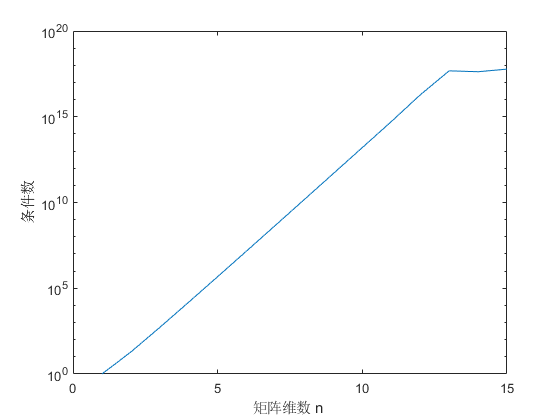

% 范围
n_range = 1:15;

% 初始化
len  = length(n_range);
cnds_sym = zeros([1, len]);
cnds_mlb = zeros([1, len]);

% 计算
for i = 1:len
    H       = hilb(n_range(i));
    lambda  = abs(eig(H));
    cnds_sym(i) = max(lambda) / min(lambda);
end

% 画图
figure
semilogy(n_range, cnds_sym)
xlabel('矩阵维数 n ')
ylabel('条件数')

可以看到，条件数是随矩阵维数指数增长的。

n大于13的部分，超出了浮点计算精度，因此出现偏差。

## 用到的函数定义

function x = Gauss(A, b, akk_min)
    
    %消元
    Ab = [A, b];
    for k = 1:length(b)
        if abs(Ab(k, k)) < akk_min
            error('出现过小主元，无法求解。')
            return
        end
        m = Ab(k+1:end, k) / Ab(k, k);
        Ab(k+1:end, k:end) = Ab(k+1:end, k:end) - m*Ab(k, k:end);
    end
    
    %回代
    A = Ab(:,1:end-1);
    b = Ab(:,end);
    x = b;
    n = length(b);
    
    x(n) = b(n) / A(n,n);
    for k = n-1:-1:1
        x(k) = ( b(k) - A(k,k+1:end)*x(k+1:end) ) / A(k,k);
    end
    
end

function x = GaussSeidel(A, b, x_0, num, err)
    L = tril(A, -1);
    U = triu(A, 1);
    D = diag(diag(A));
    
    k   = 0;
    x = inv( D + L ) * ( - U * x_0 + b );
    
    while abs(max(x-x_0)) > err
        x_0 = x;
        x = inv( D + L ) * ( - U * x_0 + b );
        k = k + 1;
        if k >= num % 迭代次数
            B = - inv( D + L ) * U;
            rho = max(abs(eig(B)));
            warning(['迭代未收敛，迭代谱半径为 ' ,num2str(rho), '，( 1 - 谱半径 = ', num2str(1-rho), ' )。'])
            break
        end
    end
end